# Make a Datastore

Instructions are in the task pane to the left. Complete and submit each task one at a time.

## Task 1

You can use wildcards to make a datastore to files or folders matching a particular pattern.

`ds` `=` `datastore``(``"data*.xlsx"``)``;`

The handwriting data files have names of the form `user003_B_2.txt`.

**TASK**

Use the `datastore` function to make a datastore to all files containing the letter M. These files have `_``M_` in their name and a `.``txt` extension. Store the datastore in a variable called `letterds`.

**Hint**

Use the `*` wildcard to make a string to represent file names of the form `XXX``_M_``XXX``.txt`. Pass this string as input to the `datastore` function and assign the result to `letterds`.

letterds = datastore("_M_.txt")

letterds =   TabularTextDatastore with properties:

                      Files: {
                             ' ...\AI_MachineLearning_DeepLearning\MachineLearningOnramp\_M_.txt'
                             }
                    Folders: {
                             ' ...\AI_MachineLearning_DeepLearning\MachineLearningOnramp'
                             }
               FileEncoding: 'UTF-8'
   AlternateFileSystemRoots: {}
         VariableNamingRule: 'modify'
          ReadVariableNames: true
              VariableNames: {'Time', 'X', 'Y' ... and 1 more}
             DatetimeLocale: en_US

  Text Format Properties:
             NumHeaderLines: 0
                  Delimiter: {' ', '\t'}
               RowDelimiter: '\r\n'
             TreatAsMissing: ''
               MissingValue: NaN

  Advanced Text Format Properties:
            TextscanFormats: {'%f', '%f', '%f' ... and 1 more}
 

## Task 2

You can use the `read` function to import the data from a file in the datastore.

`data` `=` `read``(``ds``)``;`

Using the `read` function the first time will import the data from the first file. Using it a second time will import the data from the second file, and so on.

**TASK**

Import the data from the first file into a table called `data`.

**Hint**

Pass the datastore `letterds` to the `read` function.

data=read(letterds)

data = 256×4 table
    Time       X        Y        P  
    _____    _____    _____    _____

    34806    0.775    0.228    0.042
    34808    0.775    0.227    0.255
    34808    0.775    0.227    0.255
    34825    0.774    0.221     0.44
    34833    0.774    0.214    0.569
    34850    0.773    0.199    0.745
    34866    0.772    0.188      0.8
    34886    0.772    0.176    0.851
    34900    0.773    0.173     0.88
    34944    0.777    0.194    0.894
    34949    0.778    0.201    0.896
    34975    0.784    0.228    0.899
    34995    0.789    0.249    0.923
    35000     0.79    0.251    0.931
    35018    0.791    0.248    0.995
    35058     0.79    0.209        1


## Task 3

**TASK**

Visualize the data by plotting the `X` variable of `data` on the horizontal axis and the `Y` variable on the vertical axis.

**Hint**

Pass `data.X` and `data.Y` to the `plot` function.

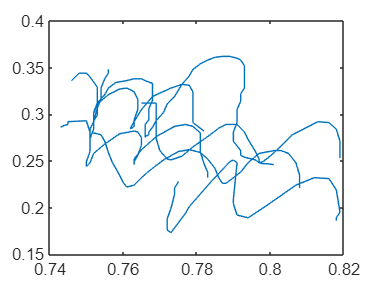

plot(data.X,data.Y)

## Task 4

Calling the `read` function again imports the data from the next file in the datastore.

**TASK**

Import and plot the data from the second file.

**Hint**

Repeat the previous two commands.

data = read(letterds)

Error using matlab.io.datastore.TabularTextDatastore/readData (line 43)
No more data to read.
Use reset method to reset the datastore to the start of the data. Before calling the read method, check if data is available to read by using the hasdata method.

Error in matlab.io.datastore.TabularDatastore/read (<a hr

plot(data.X,data.Y)

## Task 5

The `readall` function imports the data from all the files in the datastore into a single variable.

**TASK**

Use the `readall` function to import the data from all the files into a table called `data`. Visualize the data by plotting `Y` against `X`.    

**Hint**

Repeat the previous two commands, but modify the first command to use `readall` instead of `read`.

data = readall(letterds)
plot(data.X,data.Y)